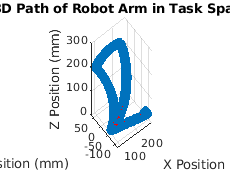

% tic;
% travelTimeMS = 5000; % Defines the travel time in milliseconds
% travelTimeS = travelTimeMS / 1000; % Travel time in seconds
% robot = Robot();
% robot.writeMotorState(true);
% 
% calculator = Lab2Step2();
 model = Model(false); % Assuming not connected to the actual robot for plotting purposes
% 
% % Define the points
% points = [
%     calculator.step2ik([80,-75,40],300);
%     calculator.step2ik([190,0,290],350);
%     calculator.step2ik([100,65,190],340);
%     calculator.step2ik([80,-75,40],300) % Returning to the first point
% ];
% 
% % Initialize arrays to store the time and positions
% times = [];
% positions = [];
% jointangles1 = [];
% % Loop through each set of angles
% for i = 1:size(points, 1)
%     % Set the joint variables to move the robot
%     angles = points(i, :);
%     robot.set_joint_vars(angles, travelTimeMS);
%     tic;
%     while toc < travelTimeS
%         jointvars = robot.read_joint_vars(true,false);
%         jointangles = jointvars(1,:);
%         jointangles1 = [jointangles1; jointangles];
%         positions = [positions;model.fk(jointangles)];
%         times = [times; toc + travelTimeS*(i-1)];
% % pause(travelTimeS); % Wait for movement to finish
%     end
%     % Record the current time and end effector position
% %     currentTime = toc; % Assuming tic is called at the beginning of the script
% %     times = [times; currentTime];
% %     pos = model.fk(angles);
% %     positions = [positions; pos]; % Use the fk method to get the position
% %     
% %     % Plot the arm if needed for each position
% %     model.plot_arm(angles);
% end



 %Plot the 3D path of the end effector in task space
figure;
plot3(positions(:, 1), positions(:, 2), positions(:, 3), '-o', ...
    'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', 'r');

% Label the plot for the 3D path
xlabel('X Position (mm)');
ylabel('Y Position (mm)');
zlabel('Z Position (mm)');
title('3D Path of Robot Arm in Task Space');
grid on;
view(3); % Adjust the view to 3D perspective

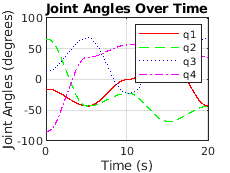


%Plotting the joing angles
figure('Name', 'Joint Angles over time');
plot(times, jointangles1(:, 1), '-r', 'DisplayName', 'q1'); hold on;
plot(times, jointangles1(:, 2), '--g', 'DisplayName', 'q2');
plot(times, jointangles1(:, 3), ':b', 'DisplayName', 'q3');
plot(times, jointangles1(:, 4), '-.m', 'DisplayName', 'q4');
hold off;
xlabel('Time (s)');
ylabel('Joint Angles (degrees)');
title('Joint Angles Over Time');
legend('show');
grid on;

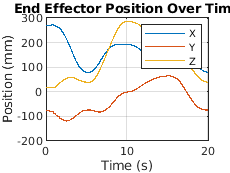

Pos=[];
Angles=jointangles1';
for i=1:size(Angles,2)
    Pos(i,:)=(M.fk(Angles(1:4,i)));
end
figure;
plot(times,Pos);
xlabel('Time (s)');
ylabel('Position (mm)');
title('End Effector Position Over Time');
legend('X','Y','Z'); % Show the legend
grid on; % Add a grid for easier reading